# Emmanuelle Chaigneau

# Serge Charpak Lab

# Figure 5 Dual color ratiometric measurements

## Figure parameters

Fig5TitleFontsize = 14 ;
Fig5LegendFontsize = 10 ;
Fig5AxisLabelFontsize = 12 ;
Fig5Linewidth = 2 ;

Figure5 = figure;
Figure5.Position = [10 10 1000 600] ;
Figure5Layout = tiledlayout(2,5);
Figure5Layout.Padding = 'tight';

## Load analysis files

load('Lambda_MuABrainTot.mat');
LambdaMuA = Lambda_MuABrainTot(:,1);
MuABrainTot = Lambda_MuABrainTot(:,2);

load('Lambda_Phi_TexasRed.mat');
LambdaPhiNAS = Lambda_Phi_TexasRed(:,1);
PhiNAS = Lambda_Phi_TexasRed(:,2) / sum (Lambda_Phi_TexasRed(:,2));

load('Lambda_Phi_FITC.mat');
LambdaPhiNB = Lambda_Phi_FITC(:,1);
PhiNB = Lambda_Phi_FITC(:,2) / sum (Lambda_Phi_FITC(:,2));

load('Lambda_MupsBrain.mat') ;
MupsBrain = Lambda_MupsBrain(:,2) ;
MuptBrain = MuABrainTot + MupsBrain ;


### Analysis parameters

CAS = 1.14 * 10^-5 ;
CB = 2 * 10^-5 ;
SigmaN = 110 / 18 ;     

Lambda1 = 500 ;
Lambda2 = 550 ;
Lambda3 = 604 ;
Lambda4 = 644 ;


### Get values of interest

BooIdxMuALambda1to2 = logical( (LambdaMuA >= Lambda1) .* (LambdaMuA <= Lambda2) ) ;
BooIdxMuALambda3to4 = logical( (LambdaMuA >= Lambda3) .* (LambdaMuA <= Lambda4) ) ;

BooIdxASLambda3to4 = logical( (LambdaPhiNAS >= Lambda3) .* (LambdaPhiNAS <= Lambda4) ) ;

BooIdxBLambda1to2 = logical( (LambdaPhiNB >= Lambda1) .* (LambdaPhiNB <= Lambda2) ) ;
BooIdxBLambda3to4 = logical( (LambdaPhiNB >= Lambda3) .* (LambdaPhiNB <= Lambda4) ) ;


## Panel A

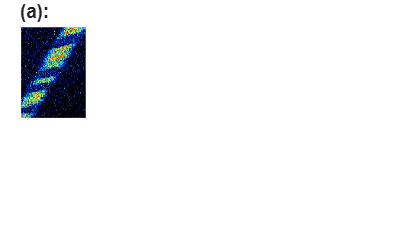

PanelA1 = nexttile([1 1]) ;

Sketch5A = imread('Cap1.jpg');
image(Sketch5A)
PanelA1.YColor = [1 1 1] ;
PanelA1.XColor = [1 1 1] ;

title('(a):', 'FontSize', Fig5TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel B

## Data from individual experiment

nexttile([1 2])


### Load data 

load FRatioVsTimeAndDepth_2024Oct11.mat

Depth = FRatioVsTimeAndDepth(:,1) ;

Time1 = FRatioVsTimeAndDepth(:,2) ;
Time2 = FRatioVsTimeAndDepth(:,3) ;
Time3 = FRatioVsTimeAndDepth(:,4) ; 
Time4 = FRatioVsTimeAndDepth(1,5) ;

FR1 = FRatioVsTimeAndDepth(:,6) / FRatioVsTimeAndDepth(1,6) ;
FR2 = FRatioVsTimeAndDepth(:,7) / FRatioVsTimeAndDepth(1,6) ;
FR3 = FRatioVsTimeAndDepth(:,8) / FRatioVsTimeAndDepth(1,6) ;
FR4 = FRatioVsTimeAndDepth(1,9) / FRatioVsTimeAndDepth(1,6) ;

TimeConcat = [Time1 ; Time2 ; Time3 ; Time4] ;
DepthConcat = [Depth; Depth; Depth; Depth(1)] ;
FRConcat = [FR1 ; FR2 ; FR3 ; FR4] / FRatioVsTimeAndDepth(1,6) ;

TimeCap1 = FRatioVsTimeAndDepth(1,2:5) ;
FRCap1 = FRatioVsTimeAndDepth(1,6:9) / FRatioVsTimeAndDepth(1,6) ;


### Fit Time course at the surface

ft = fittype( 'exp(x/T)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.StartPoint = -100;

[xData, yData] = prepareCurveData(TimeCap1, FRCap1);
[fitresultCap1, ~] = fit( xData, yData, ft, opts)

fitresultCap1 =      General model:
     fitresultCap1(x) = exp(x/T)
     Coefficients (with 95% confidence bounds):
       T =      -352.3  (-418.1, -286.5)

fitcoeffvalsCap1= coeffvalues(fitresultCap1);
Tau = fitcoeffvalsCap1(1)

Tau = -352.2858


TDCCFcorFRConcat = exp(-TimeConcat./Tau) .*FRConcat;


### Plot  data.

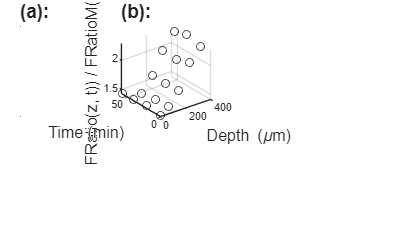

hcorrected = scatter3( DepthConcat, TimeConcat, TDCCFcorFRConcat, 'k' );

xlabel("Depth (\mum)", "FontSize", Fig5AxisLabelFontsize) ;
ylabel("Time (min)", "FontSize", Fig5AxisLabelFontsize) ;
zlabel("FRatio(z, t)) / FRatioM(0, t)", "FontSize", Fig5AxisLabelFontsize) ;
grid on

title('(b):', 'FontSize', Fig5TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel C

## Individual experiment data fiting with models and exponential

nexttile([1 2])


### Calculation of FRatioAvg

DEcorFRatioAvg2D_2025Oct11 = [TDCCFcorFRConcat(1:5), TDCCFcorFRConcat(6:10) , TDCCFcorFRConcat(11:15)] ;
DEcorFRatioAvg_2025Oct11 = mean(DEcorFRatioAvg2D_2025Oct11, 2) ;
DEcorFRatioStd_2025Oct11 = std(DEcorFRatioAvg2D_2025Oct11, 0, 2) ;

FRatioNormCC_2025Oct11 = DEcorFRatioAvg_2025Oct11 / DEcorFRatioAvg_2025Oct11(1);
FRatioNormCCStd_2025Oct11 = DEcorFRatioStd_2025Oct11 / DEcorFRatioAvg_2025Oct11(1);
zCC = 0 : 1 : 500 ;


### Optimized AbSc model

#### Find AeOpt and XBloodOpt

[AeOptCC, SumResidualsCC, R2CC, XBloodOpt] = FindAeAndXBloodOptAbScModelPhi(0.69, MuABrainTot, MupsBrain, Depth, PhiNAS, PhiNB, BooIdxMuALambda3to4, ...
    BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CAS, CB, SigmaN, FRatioNormCC_2025Oct11)

Difftest =     0.1845    0.1203    0.0750    0.0433    0.0228    0.0120    0.0103    0.0171    0.0323    0.0559    0.0880    0.1286    0.1781    0.2366    0.3044
    0.1953    0.1308    0.0844    0.0508    0.0277    0.0138    0.0083    0.0109    0.0214    0.0399    0.0664    0.1011    0.1442    0.1960    0.2567
    0.2046    0.1403    0.0930    0.0580    0.0328    0.0164    0.0079    0.0072    0.0140    0.0285    0.0506    0.0807    0.1189    0.1655    0.2209
    0.2127    0.1486    0.1008    0.0646    0.0378    0.0194    0.0086    0.0052    0.0091    0.0203    0.0391    0.0655    0.1000    0.1428    0.1942
    0.2195    0.1557    0.1076    0.0706    0.0426    0.0225    0.0098    0.0043    0.0059    0.0147    0.0308    0.0545    0.0861    0.1260    0.1746
    0.2252    0.1618    0.1135    0.0758    0.0468    0.0255    0.0114    0.0042    0.0040    0.0108    0.0249    0.0465    0.0761    0.1139    0.1605
    0.2298    0.1669    0.1185    0.0804    0.0506    0.0283    0.0130    0.0045   

LinIdxOptRow =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15


LinIdxOptCol =      7
     7
     8
     8
     8
     9
     9
     9
     9
     9
     9
     9
     9
     9
     9


IdxXBloodOpt = 9

AeOptCC = 1.8000

SumResidualsCC = 0.0022

R2CC = 0.9905

XBloodOpt = 5

#### Calculate optimized AbSc model

[PhiAbSc34AeOptCC, ThetaAbSc34AeOptCC, Sum12AeOptCC] = TricoliCoefs1234Phi(AeOptCC, 0.69, XBloodOpt*MuABrainTot/2.5, MupsBrain, ...
    zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelCC = CAS * SigmaN / CB * PhiAbSc34AeOptCC ./ Sum12AeOptCC + ThetaAbSc34AeOptCC ./ Sum12AeOptCC ;


### Absorption model

N34DivN12zAbModelCC = sum(PhiNAS(BooIdxASLambda3to4).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda3to4)*zCC/2.5)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda1to2)*zCC/2.5)) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda3to4)*zCC/2.5)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda1to2)*zCC/2.5));

AbModelBVdataCC = sum(PhiNAS(BooIdxASLambda3to4).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda3to4)*Depth'/2.5)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda1to2)*Depth'/2.5)) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda3to4)*Depth'/2.5)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda1to2)*Depth'/2.5));

SumResidualsAbModelCC = sum((FRatioNormCC_2025Oct11 - (AbModelBVdataCC / AbModelBVdataCC(1))').^2)

SumResidualsAbModelCC = 0.1285


R2AbModelCC = 1 - (sum((FRatioNormCC_2025Oct11 - (AbModelBVdataCC / AbModelBVdataCC(1))').^2) / ...
    sum((FRatioNormCC_2025Oct11 - mean(FRatioNormCC_2025Oct11)).^2))

R2AbModelCC = 0.4502

### Average AbSc model (avg values of cortex from experiments with Texas Red and Fluorescein)

[PhiAS34Avg, PhiB34Avg, PhiB12Avg] = TricoliCoefs1234Phi(1.5, 0.69, 5.2*MuABrainTot/2.5, MupsBrain, ...
    zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelCC_Avg = CAS * SigmaN / CB * PhiAS34Avg ./ PhiB12Avg + ...
    PhiB34Avg ./ PhiB12Avg ;

[PhiAS34Avg, PhiB34Avg, PhiB12Avg] = TricoliCoefs1234Phi(1.5, 0.69, 5.2*MuABrainTot/2.5, MupsBrain, ...
    Depth, PhiNAS, PhiNB, BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelCC_Avg_pH = CAS * SigmaN / CB * PhiAS34Avg ./ PhiB12Avg + PhiB34Avg ./ PhiB12Avg ;

SumResidualsAbScAvgModelCC = sum((FRatioNormCC_2025Oct11 - (FRatioAbScModelCC_Avg_pH / FRatioAbScModelCC_Avg_pH(1))').^2)

SumResidualsAbScAvgModelCC = 0.0058


R2AbScAvgModelCC = 1 - (sum((FRatioNormCC_2025Oct11 - (FRatioAbScModelCC_Avg_pH / FRatioAbScModelCC_Avg_pH(1))').^2) / ...
    sum((FRatioNormCC_2025Oct11 - mean(FRatioNormCC_2025Oct11)).^2))

R2AbScAvgModelCC = 0.9751

### Exponential fit

ftz = fittype( 'exp(u*x)', 'independent', 'x', 'dependent', 'y' );
optsz = fitoptions( 'Method', 'NonlinearLeastSquares' );
optsz.StartPoint = 0.001;
optsz.Lower= 0;

[xData, yData] = prepareCurveData(Depth, FRatioNormCC_2025Oct11);
[fitresultz, ~] = fit( xData, yData, ftz, optsz)

fitresultz =      General model:
     fitresultz(x) = exp(u*x)
     Coefficients (with 95% confidence bounds):
       u =    0.001039  (0.0008031, 0.001275)

fitcoeffvalsz = coeffvalues(fitresultz);
uData = fitcoeffvalsz(1) ;
FRatio_ExpFit_pH = exp(uData * Depth) ;

SumResidualsExpFit = sum((FRatioNormCC_2025Oct11' - (FRatio_ExpFit_pH)').^2)

SumResidualsExpFit = 0.0176


R2ExpFit = 1 - (sum((FRatioNormCC_2025Oct11' - (FRatio_ExpFit_pH)').^2) / sum((FRatioNormCC_2025Oct11' - mean(FRatioNormCC_2025Oct11,1)).^2))

R2ExpFit = 0.9249

### Plot results

hDatazAvg_2025Oct11 = errorbar(Depth, FRatioNormCC_2025Oct11, FRatioNormCCStd_2025Oct11, 'ko');
hold on
hAbModelCC = plot (zCC, N34DivN12zAbModelCC / N34DivN12zAbModelCC(1), ':') ;
hAbScModelCC = plot (zCC, FRatioAbScModelCC / FRatioAbScModelCC(1), '-') ;
hAbScModelCC_AeAvg_XbloodAvg = plot (zCC, FRatioAbScModelCC_Avg / FRatioAbScModelCC_Avg(1), '-') ;
hfitz = plot(fitresultz)

hfitz =   Line (Fitted curve) with properties:

              Color: [0.2310 0.6660 0.1960]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10 10.5000 11 11.5000 12 12.5000 13 13.5000 14 14.5000 15 15.5000 16 16.5000 17 17.5000 18 18.5000 19 19.5000 20 20.5000 21 … ] (1×1001 double)
              YData: [1 1.0005 1.0010 1.0016 1.0021 1.0026 1.0031 1.0036 1.0042 1.0047 1.0052 1.0057 1.0063 1.0068 1.0073 1.0078 1.0083 1.0089 1.0094 1.0099 1.0104 1.0110 1.0115 1.0120 1.0125 1.0131 1.0136 1.0141 1.0147 1.0152 1.0157 … ] (1×1001 double)

  Show 

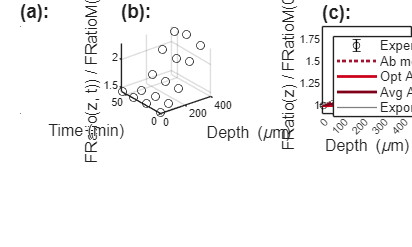

hold off

hDatazAvg_2025Oct11.MarkerSize = 5 ;
hAbModelCC.LineWidth = 2 ;
hAbModelCC.Color = [0.6350 0.0780 0.1840] ;
hAbScModelCC.LineWidth = 2 ;
hAbScModelCC.Color = [0.8 0 0.1] ;
hAbScModelCC_AeAvg_XbloodAvg.LineWidth = 2 ;
hAbScModelCC_AeAvg_XbloodAvg.Color = [0.5 0 0.1] ;
hfitz.LineWidth = 1 ;
hfitz.Color = [0.5 0.5 0.5] ;

legend('Experimental data', 'Ab model', 'Opt AbSc model', 'Avg AbSc model', 'Exponential', ...
    'Location', 'NorthWest', "FontSize", Fig5LegendFontsize);
xlabel("Depth (\mum)", "FontSize", Fig5AxisLabelFontsize)
ylabel("FRatio(z) / FRatioM(0)", "FontSize", Fig5AxisLabelFontsize)
axis([0 450 0.9 1.9]);
xticks([0 100 200 300 400]);
yticks([1 1.25 1.5 1.75]);

title('(c):', 'FontSize', Fig5TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel d

## Average FRatio versus depth within cortex

nexttile([1 2])


### Load data

load FRatioVsDepthAvg

DepthAvg = FRatioVsDepthAvg(:,1);
FRatioNormCCAvg = FRatioVsDepthAvg(:,2);
FRatioNormCCStd = FRatioVsDepthAvg(:,3);


### AbSc model

#### Find AeOpt XBloodOpt for the average data

[AeOptCCAvg, SumResidualsAeOptCCAvg, R2AeOptCCAvg, XBloodOptAvg] = FindAeAndXBloodOptAbScModelPhi(0.69, MuABrainTot, MupsBrain, DepthAvg, PhiNAS, PhiNB, ...
    BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2, CAS, CB, SigmaN, FRatioNormCCAvg)

Difftest =     0.3525    0.2311    0.1446    0.0829    0.0413    0.0171    0.0090    0.0161    0.0382    0.0749    0.1265    0.1932    0.2752    0.3730    0.4871
    0.3773    0.2560    0.1674    0.1021    0.0556    0.0253    0.0099    0.0088    0.0215    0.0479    0.0883    0.1427    0.2116    0.2953    0.3944
    0.3998    0.2790    0.1892    0.1212    0.0708    0.0357    0.0145    0.0067    0.0119    0.0300    0.0613    0.1059    0.1643    0.2369    0.3242
    0.4200    0.3001    0.2096    0.1397    0.0863    0.0473    0.0215    0.0083    0.0074    0.0188    0.0428    0.0796    0.1296    0.1933    0.2713
    0.4381    0.3193    0.2285    0.1572    0.1015    0.0595    0.0299    0.0124    0.0066    0.0127    0.0307    0.0612    0.1045    0.1612    0.2318
    0.4542    0.3368    0.2459    0.1736    0.1162    0.0717    0.0392    0.0182    0.0084    0.0101    0.0234    0.0488    0.0868    0.1378    0.2026
    0.4685    0.3524    0.2618    0.1889    0.1301    0.0838    0.0488    0.0249   

LinIdxOptRow =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15


LinIdxOptCol =      7
     8
     8
     9
     9
     9
    10
    10
    10
    10
    10
    11
    11
    11
    11


IdxXBloodOpt = 9

AeOptCCAvg = 1.4000

SumResidualsAeOptCCAvg = 0.0066

R2AeOptCCAvg = 0.9815

XBloodOptAvg = 5

#### Calculate  AbSc model for the average data

[PhiAbSc34AeOptCCAvg, ThetaAbSc34AeOptCCAvg, Sum12AeOptCCAvg] = TricoliCoefs1234Phi(AeOptCCAvg, 0.69, XBloodOptAvg * MuABrainTot/2.5, MupsBrain, ...
    zCC, PhiNAS, PhiNB, BooIdxMuALambda3to4, BooIdxASLambda3to4, BooIdxBLambda3to4, BooIdxMuALambda1to2, BooIdxBLambda1to2) ;

FRatioAbScModelCCAvg = CAS * SigmaN / CB * PhiAbSc34AeOptCCAvg ./ Sum12AeOptCCAvg + ThetaAbSc34AeOptCCAvg ./ Sum12AeOptCCAvg ;


### Absorption model

N34DivN12zAbModelCCAvg = sum(PhiNAS(BooIdxASLambda3to4).*exp(-XBloodOptAvg*MuABrainTot(BooIdxMuALambda3to4)*zCC/2.5)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda1to2)*zCC/2.5)) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda3to4)*zCC/2.5)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda1to2)*zCC/2.5));

AbModelBVdataCCAvg = sum(PhiNAS(BooIdxASLambda3to4).*exp(-XBloodOptAvg*MuABrainTot(BooIdxMuALambda3to4)*DepthAvg'/2.5)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda1to2)*DepthAvg'/2.5)) ...
          + sum(PhiNB(BooIdxBLambda3to4).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda3to4)*DepthAvg'/2.5)) ...
          ./ sum(PhiNB(BooIdxBLambda1to2).*exp(-XBloodOpt*MuABrainTot(BooIdxMuALambda1to2)*DepthAvg'/2.5));

SumResidualsAbModelCCAvg = sum((FRatioNormCCAvg - (AbModelBVdataCCAvg / AbModelBVdataCCAvg(1))').^2)

SumResidualsAbModelCCAvg = 0.2310


R2AbModelCCAvg = 1 - (sum((FRatioNormCCAvg - (AbModelBVdataCCAvg / AbModelBVdataCCAvg(1))').^2) / sum((FRatioNormCCAvg - mean(FRatioNormCCAvg)).^2))

R2AbModelCCAvg = 0.3534

### Exponential fit

[xDataAvg, yDataAvg] = prepareCurveData(DepthAvg, FRatioNormCCAvg);
[fitresultzAvg, gof] = fit( xDataAvg, yDataAvg, ftz, optsz)

fitresultzAvg =      General model:
     fitresultzAvg(x) = exp(u*x)
     Coefficients (with 95% confidence bounds):
       u =    0.001089  (0.0009938, 0.001184)

gof = struct with fields:
           sse: 0.0141
       rsquare: 0.9606
           dfe: 8
    adjrsquare: 0.9606
          rmse: 0.0419


fitcoeffvalszAvg = coeffvalues(fitresultzAvg);
ConfMatFitzAvg = confint(fitresultzAvg,0.95);
uDataAvg = fitcoeffvalszAvg(1) ;


### Plot results

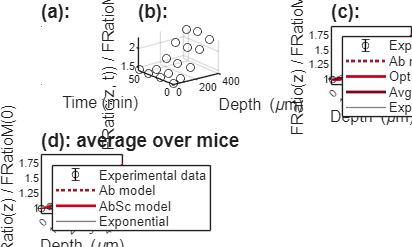

hDatazAvg = errorbar(DepthAvg, FRatioNormCCAvg, FRatioNormCCStd, 'ko') ;
hold on
hAbModelCCAvg = plot (zCC, N34DivN12zAbModelCCAvg / N34DivN12zAbModelCCAvg(1), ':') ;
hAbScModelCCAvg = plot (zCC, FRatioAbScModelCCAvg / FRatioAbScModelCCAvg(1), '-') ;
hfitAvg = plot(fitresultzAvg) ;
hold off

hDatazAvg.MarkerSize = 5 ;
hAbModelCCAvg.LineWidth = Fig5Linewidth ;
hAbModelCCAvg.Color = [0.6350 0.0780 0.1840] ;
hAbScModelCCAvg.LineWidth = Fig5Linewidth ;
hAbScModelCCAvg.Color = [0.8 0 0.1] ;
hfitAvg.LineWidth = 1 ;
hfitAvg.Color = [0.5 0.5 0.5] ;

legend('Experimental data', 'Ab model', 'AbSc model', 'Exponential','Location', 'NorthWest', ...
    "FontSize", Fig5LegendFontsize) ;
xlabel("Depth (\mum)", "FontSize", Fig5AxisLabelFontsize)
ylabel("FRatio(z) / FRatioM(0)", "FontSize", Fig5AxisLabelFontsize)
axis([0 450 0.9 1.9]);
xticks([0 100 200 300 400]);
yticks([1 1.25 1.5 1.75]);

title('(d): average over mice', 'FontSize', Fig5TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel e

## Statistics

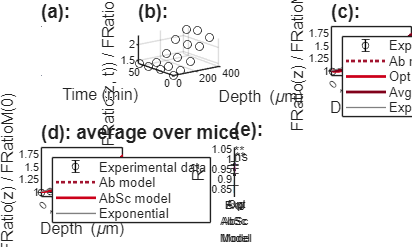

nexttile([1 1])

load Results_ExpFit_AbScModel.mat

R2_ExpFit = Results_ExpFit_AbScModel(:,1) ;
R2_AbScModelOpt = Results_ExpFit_AbScModel(:,2) ;
R2_AbScModelAvg = Results_ExpFit_AbScModel(:,3) ;
MSE_ExpFit = Results_ExpFit_AbScModel(:,4) ./ Results_ExpFit_AbScModel(:,7);
MSE_AbScModelOpt = Results_ExpFit_AbScModel(:,5) ./ Results_ExpFit_AbScModel(:,7);
MSE_AbScModelAvg = Results_ExpFit_AbScModel(:,6) ./ Results_ExpFit_AbScModel(:,7);

R2 = [R2_ExpFit , R2_AbScModelAvg, R2_AbScModelOpt, ] ;
SumRes = [MSE_ExpFit , MSE_AbScModelAvg, MSE_AbScModelOpt] ;

Avg_R2_ExpFit = mean(R2_ExpFit) ;
Avg_R2_AbScModelOpt = mean(R2_AbScModelOpt) ;
Avg_R2_AbScModelAvg = mean(R2_AbScModelAvg) ;
Mean_R2 = [Avg_R2_ExpFit Avg_R2_AbScModelAvg  Avg_R2_AbScModelOpt ] ;

Sdev_R2_ExpFit = std(R2_ExpFit) ;
Sdev_R2_AbScModelOpt = std(R2_AbScModelOpt) ;
Sdev_R2_AbScModelAvg = std(R2_AbScModelAvg) ;
Sdev_R2 = [Sdev_R2_ExpFit Sdev_R2_AbScModelAvg  Sdev_R2_AbScModelOpt ] ;

Avg_MSE_ExpFit = mean(MSE_ExpFit) ;
Avg_MSE_AbScModelOpt = mean(MSE_AbScModelOpt) ;
Avg_MSE_AbScModelAvg = mean(MSE_AbScModelAvg) ;
Mean_MSE = [Avg_MSE_ExpFit Avg_MSE_AbScModelAvg Avg_MSE_AbScModelOpt ] ;

Sdev_MSE_ExpFit = std(MSE_ExpFit) ;
Sdev_MSE_AbScModelOpt = std(MSE_AbScModelOpt) ;
Sdev_MSE_AbScModelAvg = std(MSE_AbScModelAvg) ;
Sdev_MSE = [Sdev_MSE_ExpFit Sdev_MSE_AbScModelAvg Sdev_MSE_AbScModelOpt ] ;

x = [1 2 3] ;
x1 = [1, 1.9];
y1 = [1 , 1];
x2 = [2.1, 3];
x3 = [1, 3];
y2 = [1.03 , 1.03];

bar(x,Mean_R2,0.5,'FaceColor',[0.5 0.5 0.5]) ;
hold on
errorbar(x, Mean_R2, Sdev_R2, 'k.') ;
plot(x, R2) ;
line(x1, y1, 'Color','k','Linewidth', 2);
line(x2, y1, 'Color','k','Linewidth', 2);
line(x3, y2, 'Color','k','Linewidth', 2);
hold off

axis([0.5 3.5 0.81 1.06]) ;
ax = gca ;
ax.XTick = [1 2 3] ; 
ax.XTickLabels = {'Exp','  Avg \newline AbSc \newline Model ', '  Opt \newline AbSc \newline Model'} ;
ax.XTickLabelRotation = 0 ;
ylabel("R^2", "FontSize", Fig5AxisLabelFontsize)

text(1.3, 1.015,'ns')
text(2.4, 1.01,'**')
text(1.9, 1.04,'**')

title('(e):', 'FontSize', Fig5TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel f

## Statistics

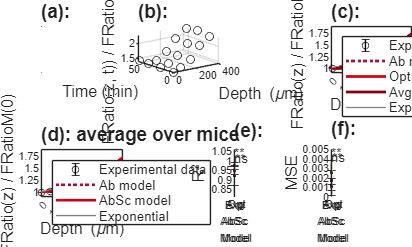

nexttile([1 1])

yf1 = [0.004 , 0.004];
yf2 = [0.0045 , 0.0045];

bar(x,Mean_MSE,0.5,'FaceColor',[0.5 0.5 0.5]) ;
hold on
errorbar(x, Mean_MSE, Sdev_MSE, 'k.') ;
plot(x, SumRes) ;
line(x1, yf1, 'Color','k','Linewidth', 2);
line(x2, yf1, 'Color','k','Linewidth', 2);
line(x3, yf2, 'Color','k','Linewidth', 2);
hold off

axis([0.5 3.5 0 0.005]) ;
ax = gca ;
ax.XTick = [1 2 3] ; 
ax.XTickLabels = {'Exp','  Avg \newline AbSc \newline Model ', '  Opt \newline AbSc \newline Model'} ;
ax.XTickLabelRotation = 0 ;
ylabel("MSE", "FontSize", Fig5AxisLabelFontsize)
yticks([0 0.001 0.002 0.003 0.004 0.005]);
yticklabels({'0', '0.001', '0.002', '0.003', '0.004', '0.005'});

text(1.3, 0.0042,'ns')
text(2.4, 0.0041,'**')
text(1.9, 0.0046,'**')

title('(f):', 'FontSize', Fig5TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel g

## Role of absorption in the AbSc model

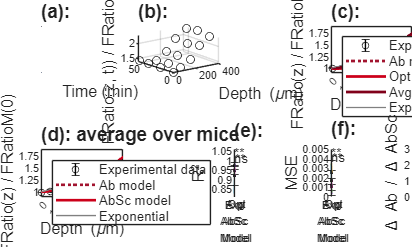

nexttile([1 1])

FRAbVsAbSc = (N34DivN12zAbModelCCAvg / N34DivN12zAbModelCCAvg(1) - 1) ./ (FRatioAbScModelCCAvg / FRatioAbScModelCCAvg(1) - 1) ;

hAbVsAbSc = plot (zCC, FRAbVsAbSc, ':') ;

hAbVsAbSc.LineWidth = Fig5Linewidth ;
hAbVsAbSc.Color = [0.6350 0.0780 0.1840] ;

xlabel("Depth (\mum)", "FontSize", Fig5AxisLabelFontsize)
ylabel("\Delta Ab / \Delta AbSc", "FontSize", Fig5AxisLabelFontsize)
axis([0 450 0 3]);

title('(g):', 'FontSize', Fig5TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';